clearvars -except tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada


## Arfada

ts=linspace(0,tMax_a,50)

$$ts = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccc} 0 & \frac{\sqrt{1635}}{5341} & \frac{2\,\sqrt{1635}}{5341} & \frac{3\,\sqrt{1635}}{5341} & \frac{4\,\sqrt{1635}}{5341} & \frac{5\,\sqrt{1635}}{5341} & \frac{6\,\sqrt{1635}}{5341} & \frac{\sqrt{1635}}{763} & \frac{8\,\sqrt{1635}}{5341} & \frac{9\,\sqrt{1635}}{5341} & \frac{10\,\sqrt{1635}}{5341} & \frac{11\,\sqrt{1635}}{5341} & \frac{12\,\sqrt{1635}}{5341} & \frac{13\,\sqrt{1635}}{5341} & \frac{2\,\sqrt{1635}}{763} & \frac{15\,\sqrt{1635}}{5341} & \frac{16\,\sqrt{1635}}{5341} & \frac{17\,\sqrt{1635}}{5341} & \frac{18\,\sqrt{1635}}{5341} & \frac{19\,\sqrt{1635}}{5341} & \frac{20\,\sqrt{1635}}{5341} & \frac{3\,\sqrt{1635}}{763} & \frac{22\,\sqrt{1635}}{5341} & \frac{23\,\sqrt{1635}}{5341} & \frac{24\,\sqrt{1635}}{5341} & \frac{25\,\sqrt{1635}}{5341} & \frac{26\,\sqrt{1635}}{5341} & \frac{27\,\sqrt{1635}}{5341} & \frac{4\,\sqrt{1635}}{763} & \frac{29\,\sqrt{1635}}{5341} & \frac{30\,\sqrt{1635}}{5341} & \frac{31\,\sqrt{1635}}{5341} & \frac{32\,\sqrt{1635}}{5341} & \frac{33\,\sqrt{1635}}{5341} & \frac{34\,\sqrt{1635}}{5341} & \frac{5\,\sqrt{1635}}{763} & \frac{36\,\sqrt{1635}}{5341} & \frac{37\,\sqrt{1635}}{5341} & \frac{38\,\sqrt{1635}}{5341} & \frac{39\,\sqrt{1635}}{5341} & \frac{40\,\sqrt{1635}}{5341} & \frac{41\,\sqrt{1635}}{5341} & \frac{6\,\sqrt{1635}}{763} & \frac{43\,\sqrt{1635}}{5341} & \frac{44\,\sqrt{1635}}{5341} & \frac{45\,\sqrt{1635}}{5341} & \frac{46\,\sqrt{1635}}{5341} & \frac{47\,\sqrt{1635}}{5341} & \frac{48\,\sqrt{1635}}{5341} & \frac{\sqrt{1635}}{109} \end{array}\right)$$

balanceo=0

balanceo = 0

cabeceo=0

cabeceo = 0

arfada=Fz_arfada;
largoB=0.4

largoB = 0.4000

largoM=0.2

largoM = 0.2000

AlturaPlaca=0.55

AlturaPlaca = 0.5500

PosXBiela=0.1

PosXBiela = 0.1000

PosYBiela=-0.4

PosYBiela = -0.4000

PosXEje=0

PosXEje = 0

PosYEje=-0.4

PosYEje = -0.4000

PosZEje=0.2

PosZEje = 0.2000

%theta1
FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaArfadaW=diff(FthetaArfada);
FthetaArfadaAlpha=diff(FthetaArfadaW);
%plot(t,Ftheta())

### Valores arfada


angulosArfada=subs(FthetaArfada,ts)*180/pi

VelocidadAngularArfada=subs(FthetaArfadaW,ts)*180/pi;
AceleracionAngularArfada=subs(FthetaArfadaAlpha,ts)*180/pi;

### Gráficas arfada

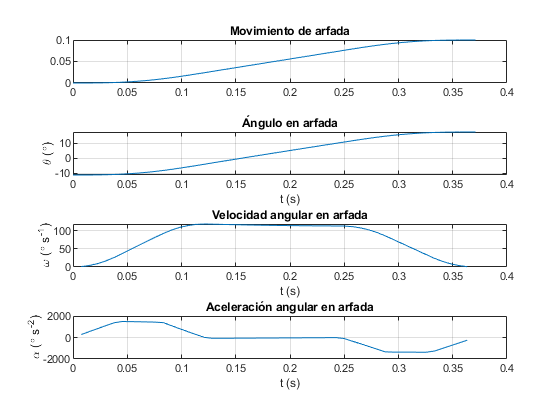

figure()
subplot(4,1,1)
plot(ts,arfada(ts))
title('Movimiento de arfada')
grid on
subplot(4,1,2)
plot(ts,angulosArfada)
title('Ángulo en arfada')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(4,1,3)
plot(ts,VelocidadAngularArfada)
title('Velocidad angular en arfada')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(4,1,4)
plot(ts,AceleracionAngularArfada)
title('Aceleración angular en arfada')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

## Cabeceo

ts=linspace(0,tMax_c,50);
balanceo=15*pi/180; %valor de balanceo en radianes
cabeceo=Ftheta_c;
arfada=0; %valor de arfada

largoB=0.4;
largoM=0.2;
AlturaPlaca=0.55;
PosXBiela=0.1;
PosYBiela=-0.4;
PosXEje=0;
PosYEje=-0.4;
PosZEje=0.2;
%theta1
FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaCabeceoW=diff(FthetaCabeceo);
FthetaCabeceoAlpha=diff(FthetaCabeceoW);
%plot(t,Ftheta())

### Valores cabeceo

angulosCabeceo=subs(FthetaCabeceo,ts)*180/pi;
VelocidadAngularCabeceo=subs(FthetaCabeceoW,ts)*180/pi;
AceleracionAngularCabeceo=subs(FthetaCabeceoAlpha,ts)*180/pi;


### Gráficas cabeceo

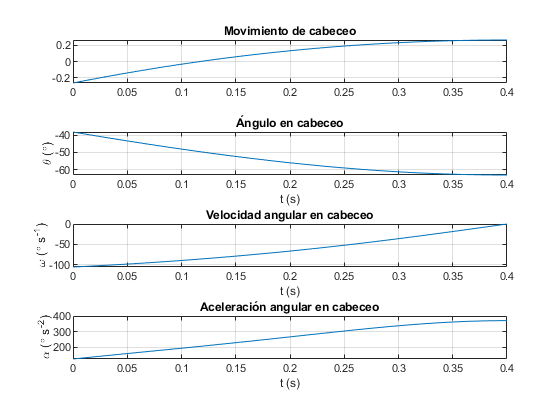

figure()
subplot(4,1,1)
plot(ts,cabeceo(ts))
title('Movimiento de cabeceo')
grid on
subplot(4,1,2)
plot(ts,angulosCabeceo)
title('Ángulo en cabeceo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(4,1,3)
plot(ts,VelocidadAngularCabeceo)
title('Velocidad angular en cabeceo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(4,1,4)
plot(ts,AceleracionAngularCabeceo)
title('Aceleración angular en cabeceo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on